# Pointcloud construction

% compute and save the point clouds for the original images
compute_point_cloud(1)
compute_point_cloud(2)
compute_point_cloud(3)

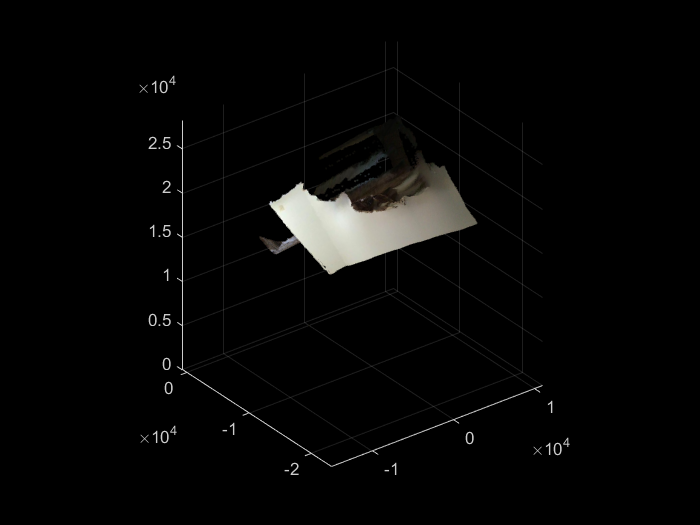

% display the point clouds
load('pointCloudImage_1.mat', 'world_coords');
rgb = uint8(world_coords(:,4:6));
ptCloud = pointCloud(world_coords(:,1:3),'Color',rgb);
pcshow(ptCloud)

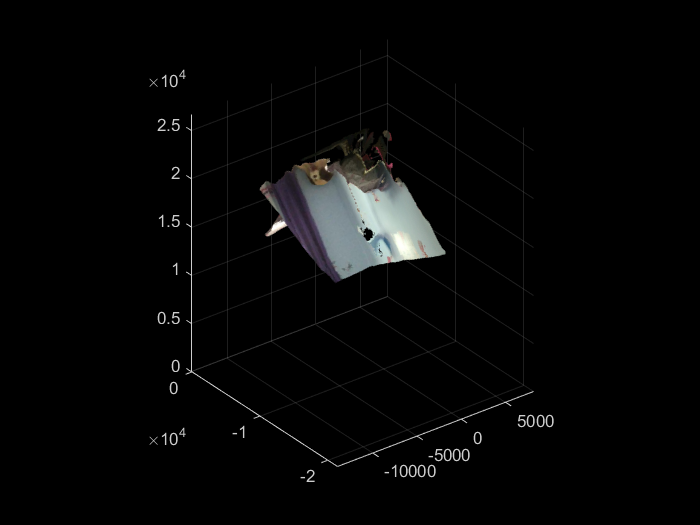


load('pointCloudImage_2.mat', 'world_coords');
rgb = uint8(world_coords(:,4:6));
ptCloud = pointCloud(world_coords(:,1:3),'Color',rgb);
pcshow(ptCloud)

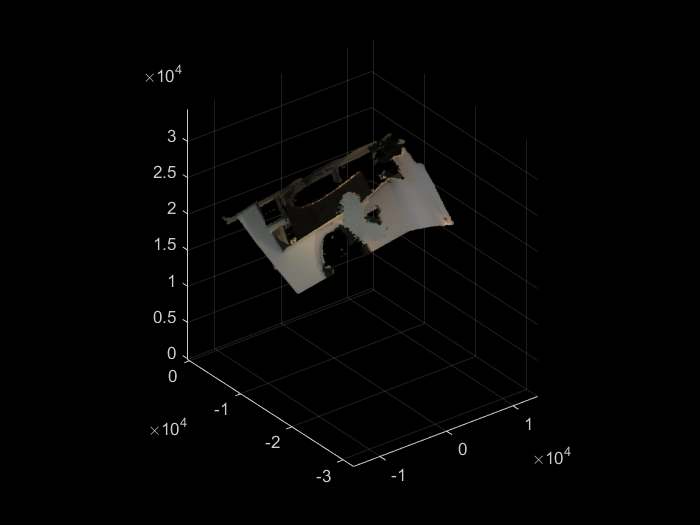


load('pointCloudImage_3.mat', 'world_coords');
rgb = uint8(world_coords(:,4:6));
ptCloud = pointCloud(world_coords(:,1:3),'Color',rgb);
pcshow(ptCloud)

# Rotation and translation simulation

% again, save the point clouds for original images
% don't have to run this part if the sections above are already run
compute_point_cloud(1)
compute_point_cloud(2)
compute_point_cloud(3)

The total amounts for rotation and translation are specified by the variables "angle" and "translation.“

These amounts are applied to points in camera coordinate system, so the directions of rotation and translation are opposite to camera movement.

The last parameter of generate_transform_video is a logical variable that determines whether or not to generate enhanced version of the video.

Also:

 if the rotation is around the x-axis, then the translation is applied to the z-axis,

 if the rotation is around the y-axis, then the translation is applied to the x-axis, 

 if the rotation is around the z-axis, then the translation is applied to the y-axis.

Please note that videos that contain a large number of frames (e.g. a 5-second video of framerate 30 has 150 frames) might take a considerable amount of time to generate (take around 4 sec per frame for enhanced video, 0.2 sec per frame for original video on my laptop).

% generate enhanced videos for image 1
video_length = 5; % 5 seconds
framerate = 30; % 30 frames per second

angle = pi/4;
translation = 10000;

generate_transform_video(1, angle, 'x', translation, video_length, framerate, true)
generate_transform_video(1, angle, 'y', -translation, video_length, framerate, true)
generate_transform_video(1, angle, 'z', translation, video_length, framerate, true)

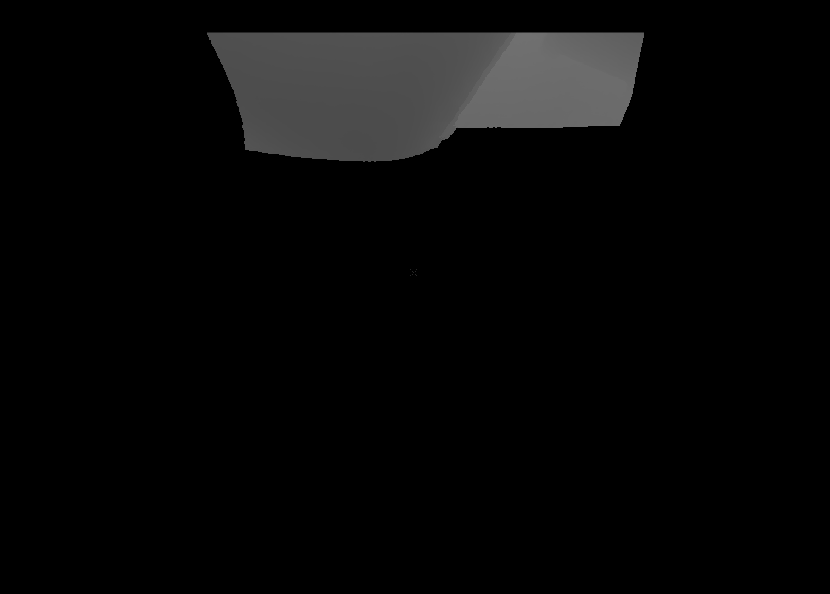

% display the result for each movement
angle = pi/4;
translation = 10000;
[depth_x, rgb_x] = compute_2D_projection_enhanced(1, angle, 'x', [0;0;translation]);
[depth_y, rgb_y] = compute_2D_projection_enhanced(1, angle, 'y', [-translation;0;0]);
[depth_z, rgb_z] = compute_2D_projection_enhanced(1, angle, 'z', [0;translation;0]);
imshow(depth_x)

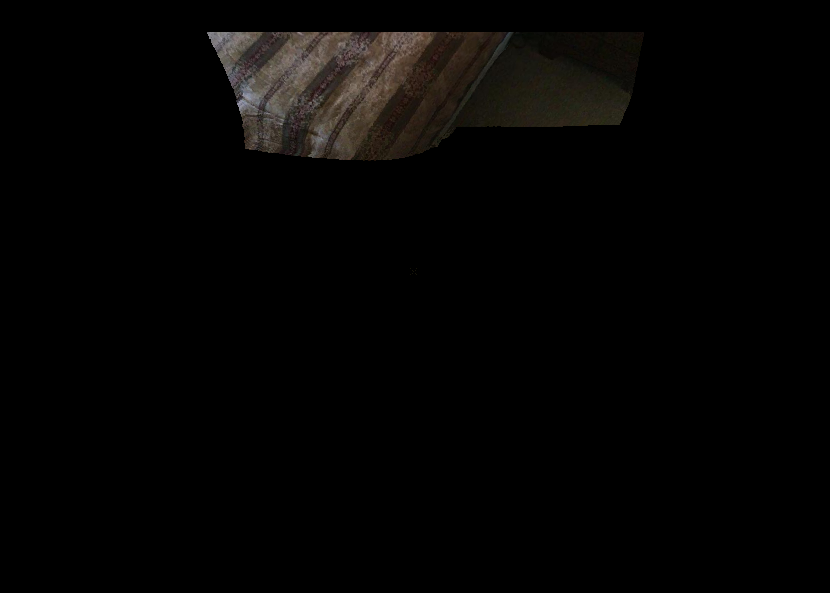

imshow(rgb_x)

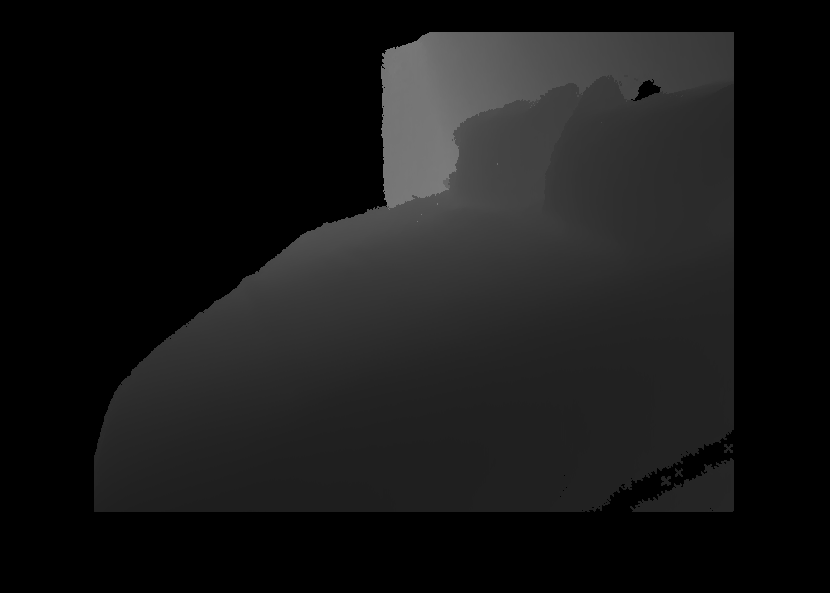

imshow(depth_y)

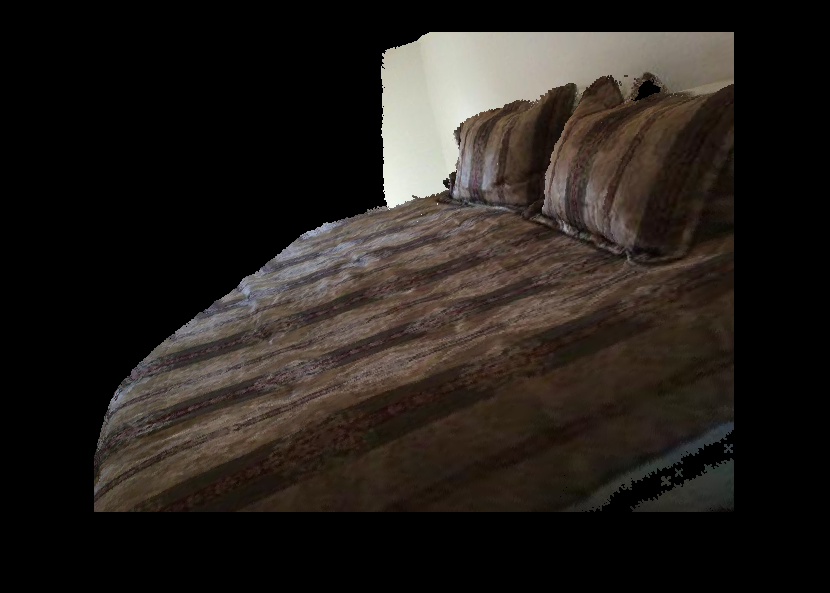

imshow(rgb_y)

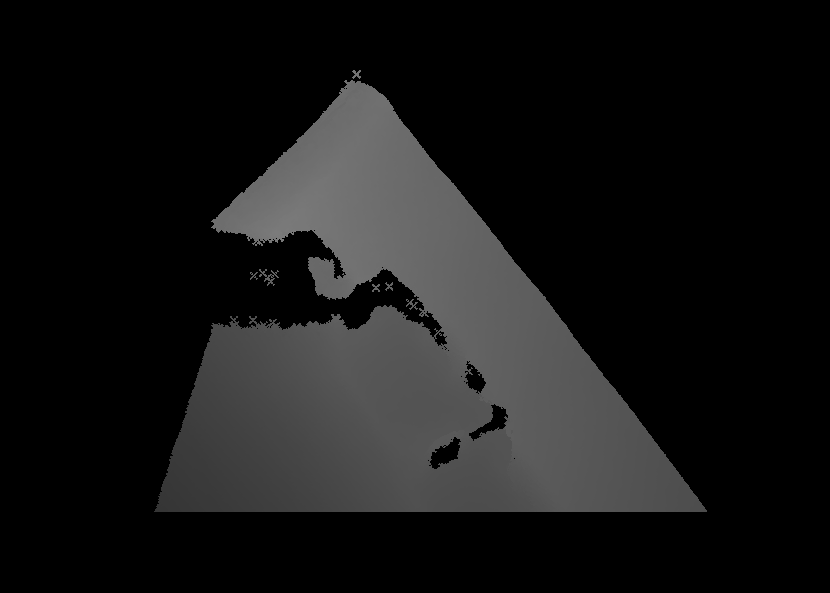

imshow(depth_z)

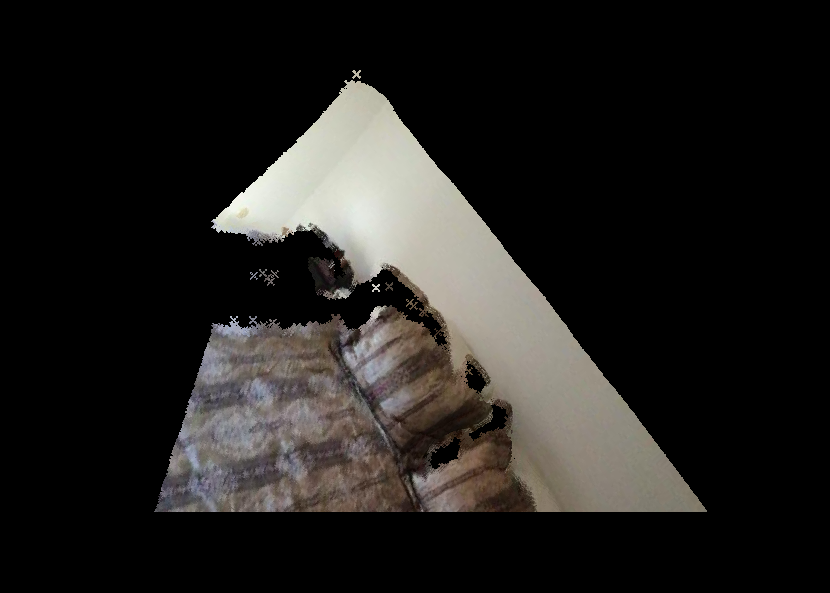

imshow(rgb_z)

% generate enhanced videos for image 2
video_length = 5; % 5 seconds
framerate = 30; % 30 frames per second

angle = pi/4;
translation = 10000;

generate_transform_video(2, angle, 'x', translation, video_length, framerate, true)
generate_transform_video(2, angle, 'y', -translation, video_length, framerate, true)
generate_transform_video(2, angle, 'z', translation, video_length, framerate, true)

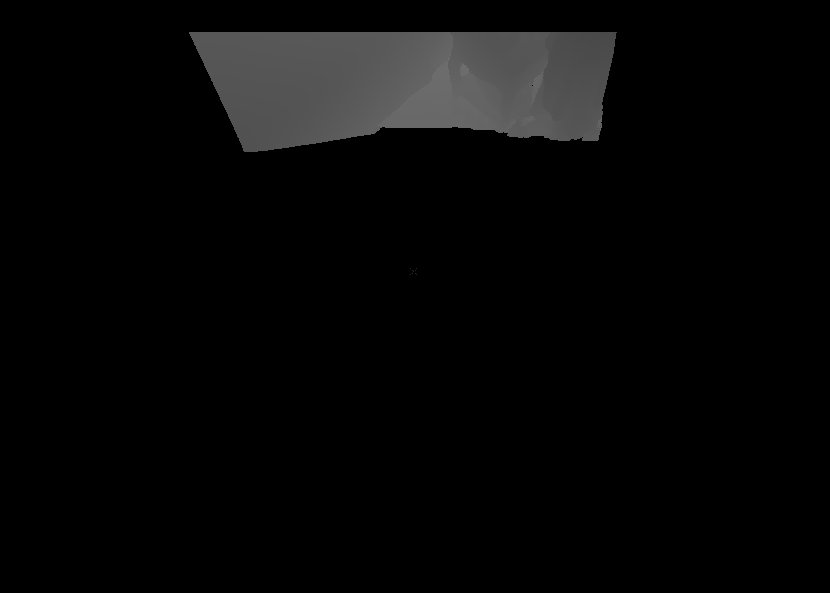

% display the result for each movement
angle = pi/4;
translation = 10000;
[depth_x, rgb_x] = compute_2D_projection_enhanced(2, angle, 'x', [0;0;translation]);
[depth_y, rgb_y] = compute_2D_projection_enhanced(2, angle, 'y', [-translation;0;0]);
[depth_z, rgb_z] = compute_2D_projection_enhanced(2, angle, 'z', [0;translation;0]);
imshow(depth_x)

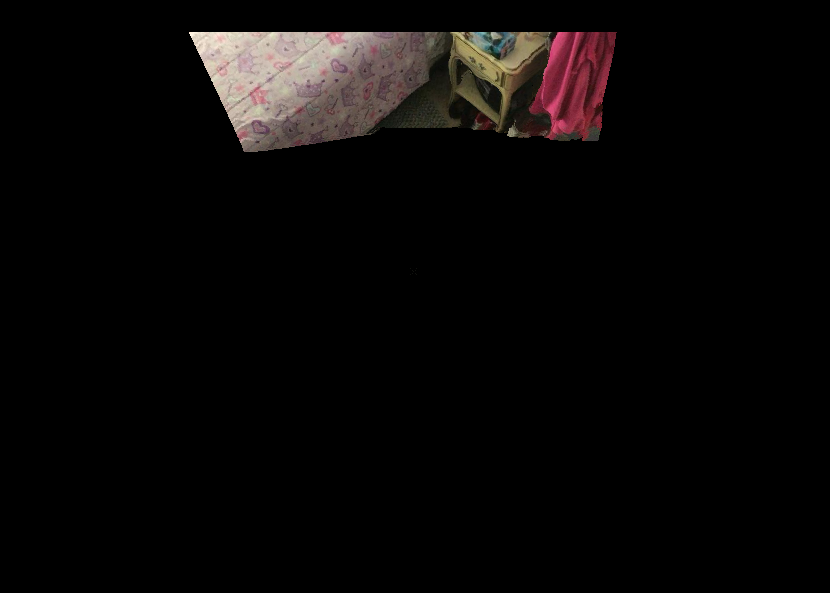

imshow(rgb_x)

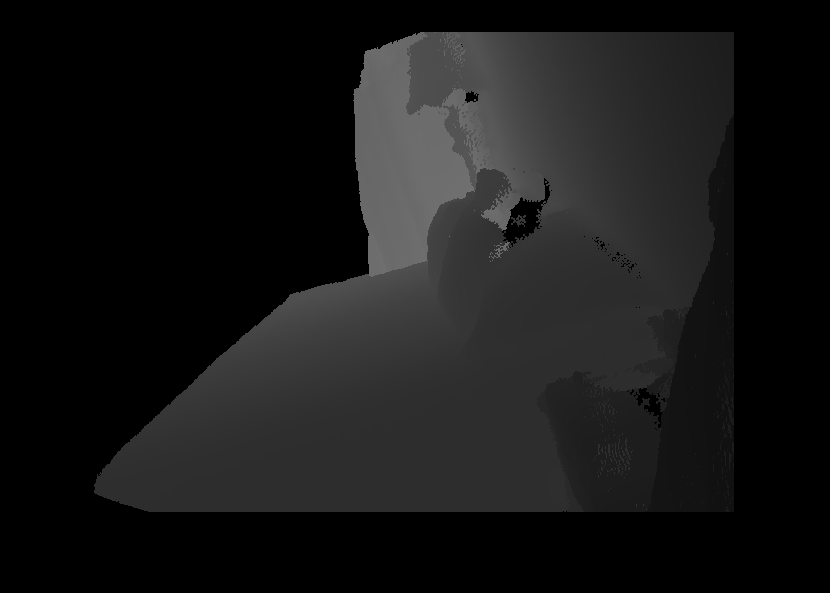

imshow(depth_y)

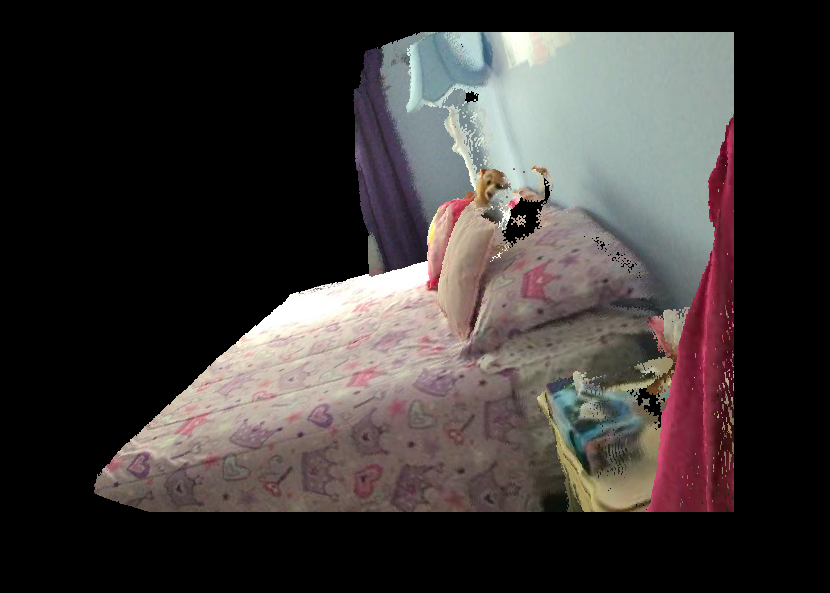

imshow(rgb_y)

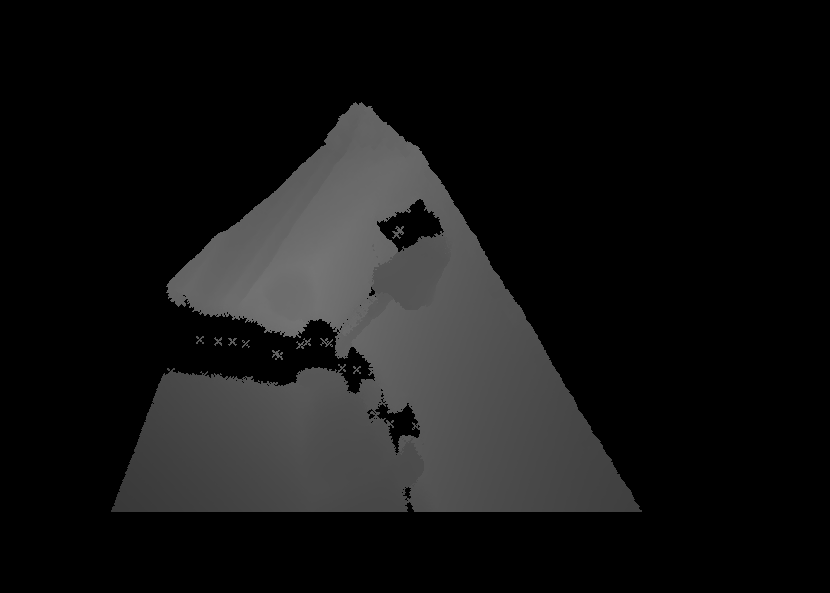

imshow(depth_z)

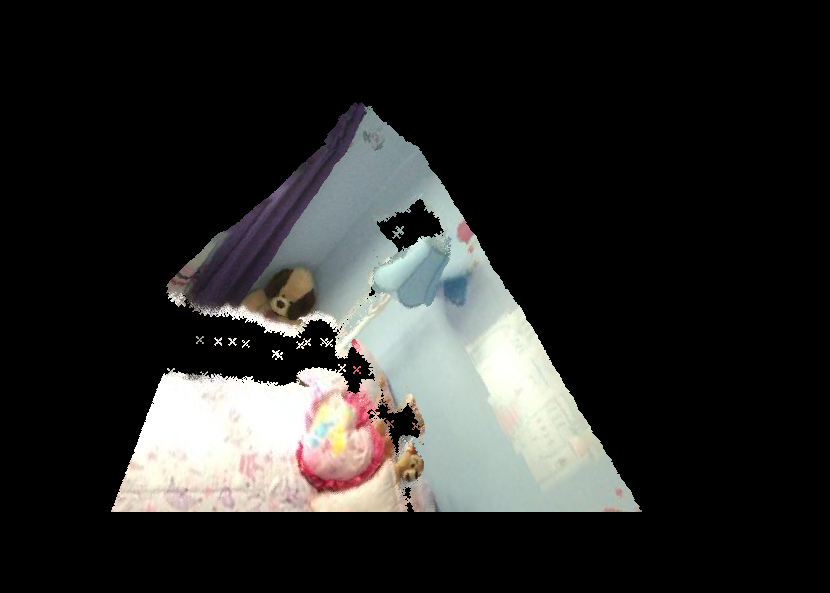

imshow(rgb_z)

% generate enhanced videos for image 3
video_length = 5; % 5 seconds
framerate = 30; % 30 frames per second

angle = pi/4;
translation = 10000;

generate_transform_video(3, angle, 'x', translation, video_length, framerate, true)
generate_transform_video(3, angle, 'y', -translation, video_length, framerate, true)
generate_transform_video(3, angle, 'z', translation, video_length, framerate, true)

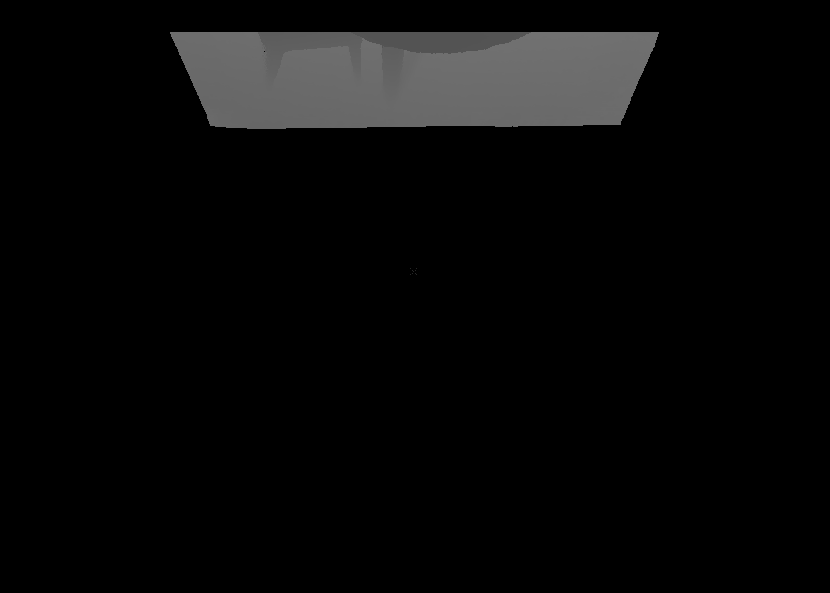


% display the result for each movement
angle = pi/4;
translation = 10000;
[depth_x, rgb_x] = compute_2D_projection_enhanced(3, angle, 'x', [0;0;translation]);
[depth_y, rgb_y] = compute_2D_projection_enhanced(3, angle, 'y', [-translation;0;0]);
[depth_z, rgb_z] = compute_2D_projection_enhanced(3, angle, 'z', [0;translation;0]);
imshow(depth_x)

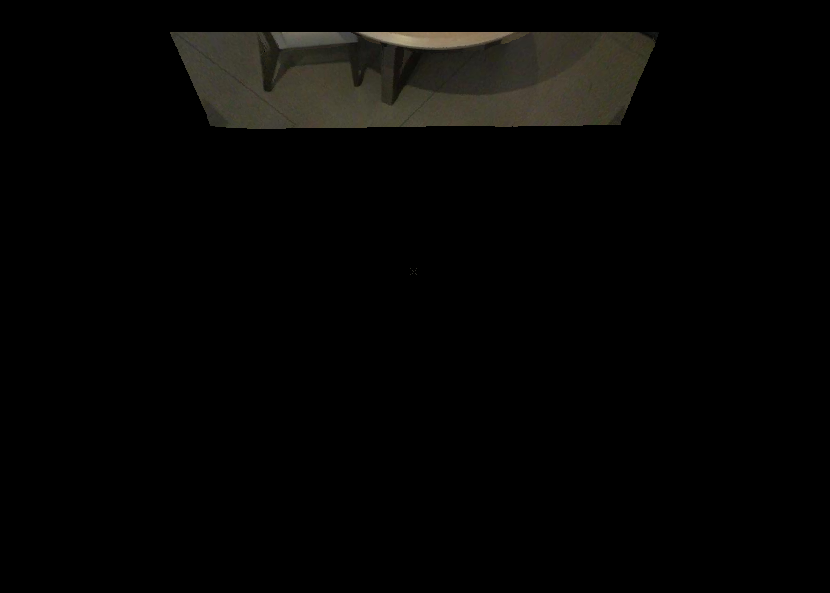

imshow(rgb_x)

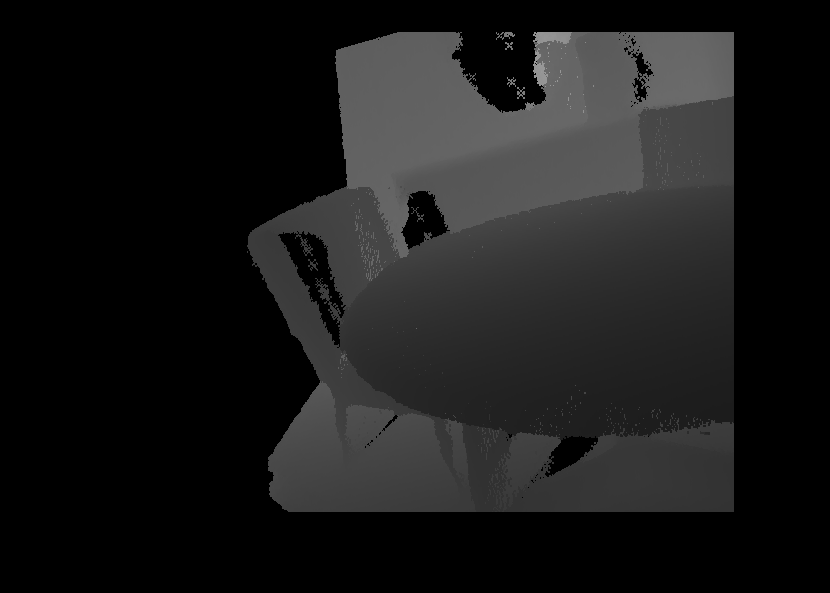

imshow(depth_y)

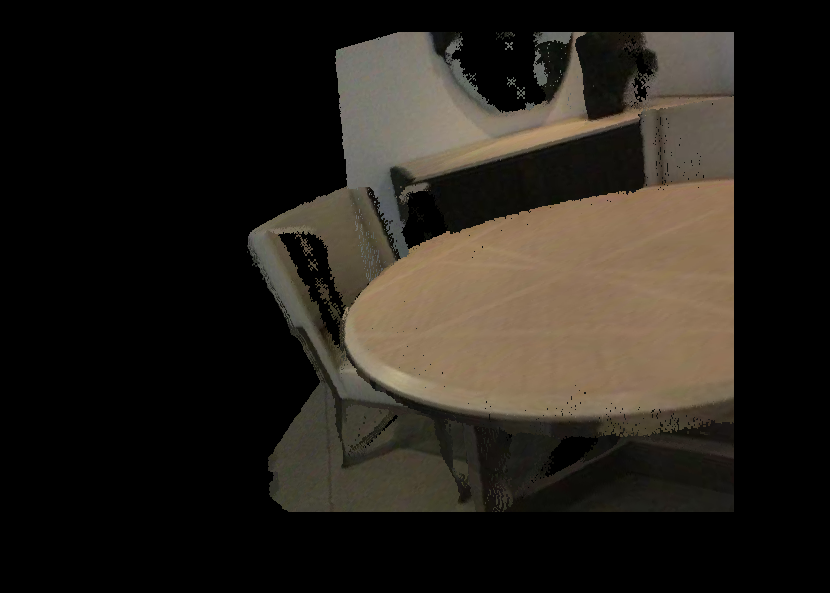

imshow(rgb_y)

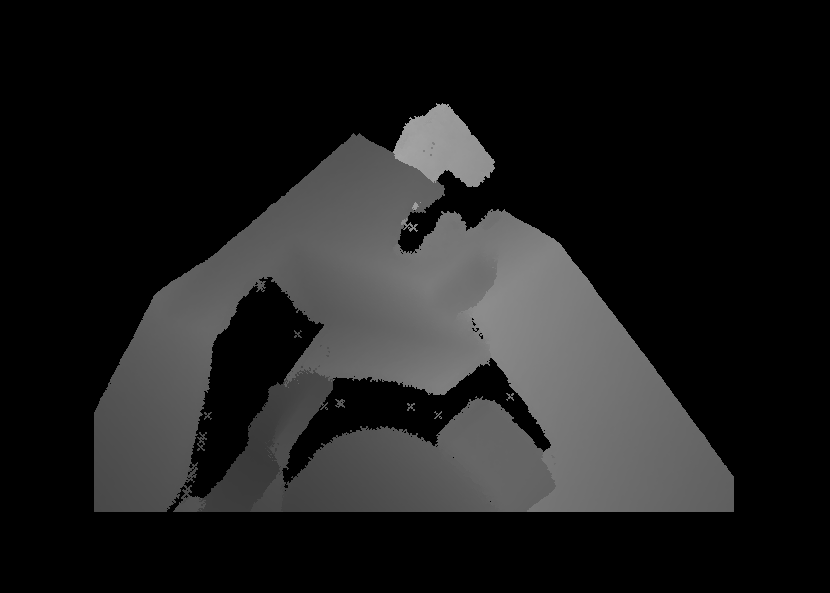

imshow(depth_z)

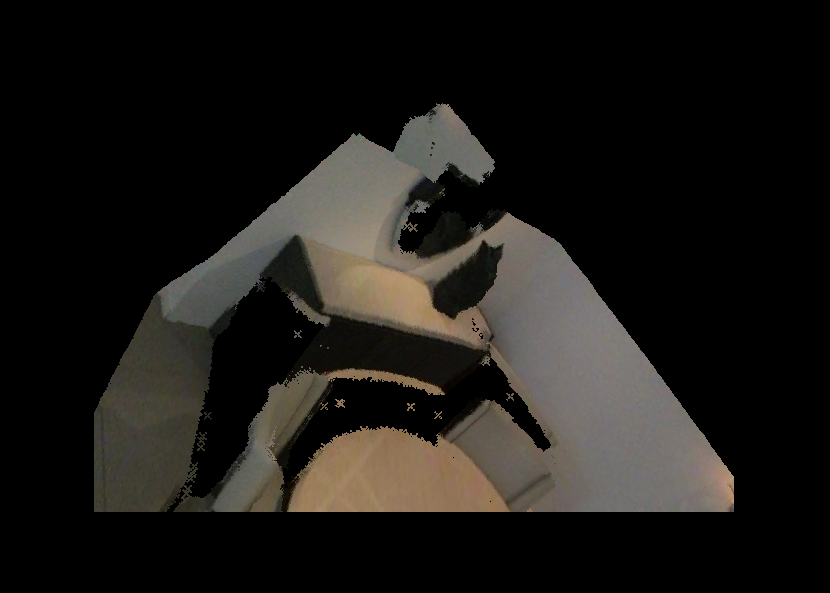

imshow(rgb_z)